### load dataset - simple contrast (dummy coding) stim Vicarious

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

con_list = dir(fullfile(mount_dir, '*/con_0025.nii'));
spm('Defaults','fMRI')
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 24360228 bytes
Loading image number:    61
Elapsed time is 223.654575 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5954046  Bit rate: 22.51 bits


### `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              18:37:12 - 26/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


drawnow; snapnow

### run robfit

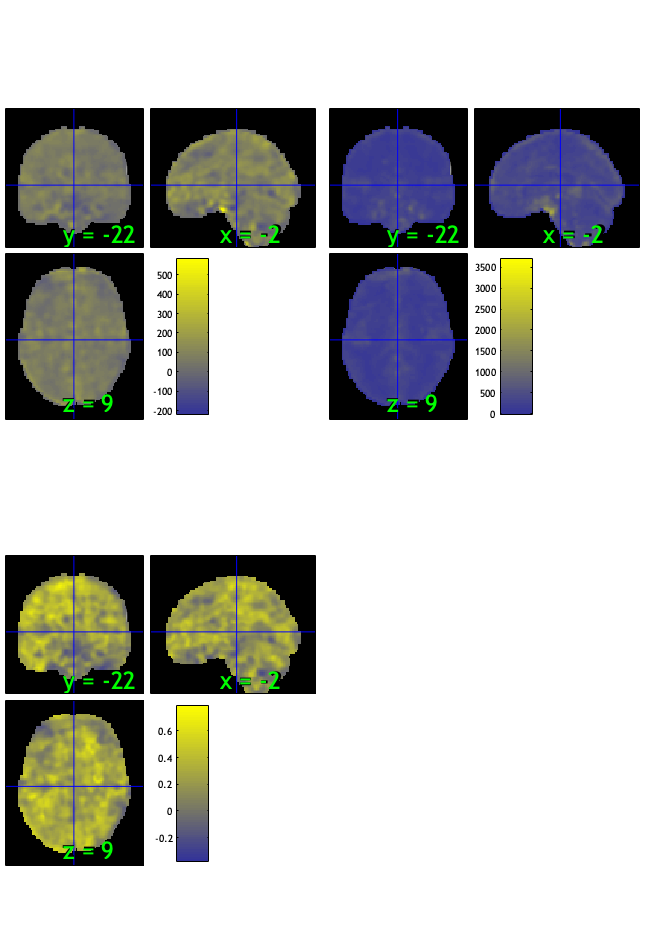

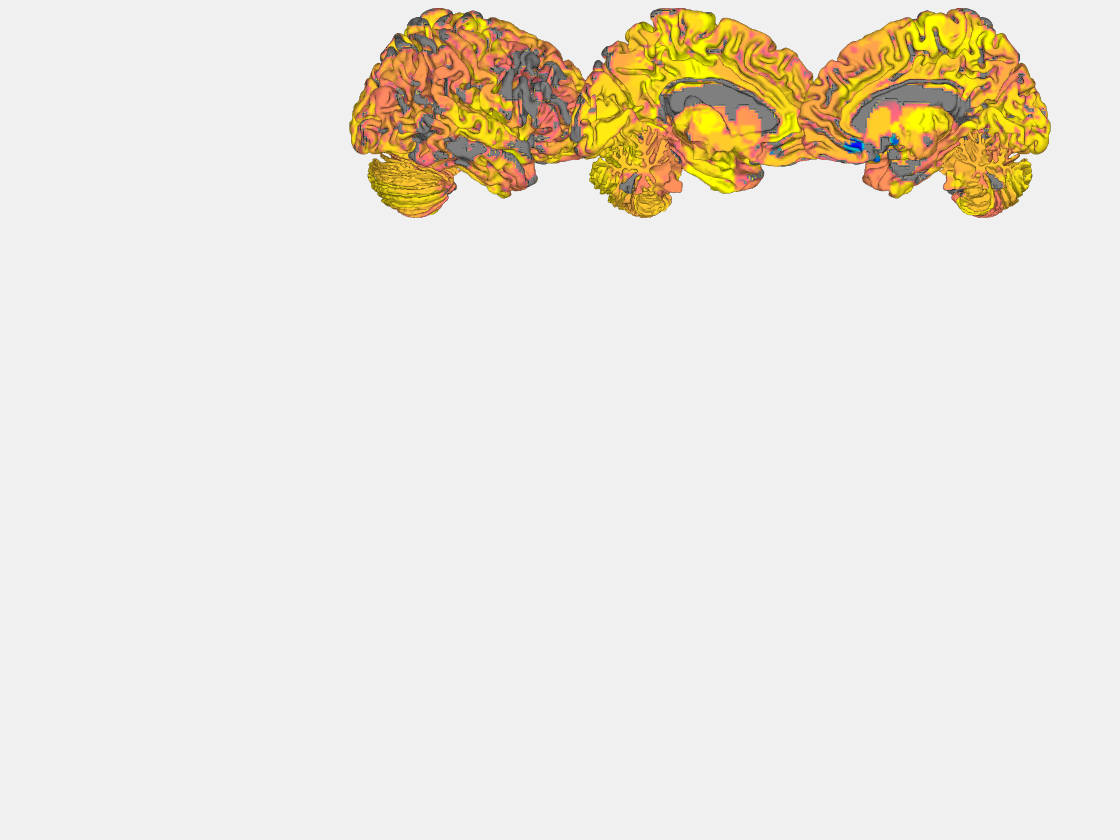

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat
Initializing nodes to match regions.
Updating node response data.
Updating obj.connectivity.nodes.
Updating obj.connectivity.nodes.
Updating region averages.
Updating obj.connectivity.regions.
Updating obj.connectivity.regions.
__________________________________________________________________
Input image diagnostic information
__________________________________________________________________
Retained 16 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.82%
Expected 3.05 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 41 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 21.31%
Expected 3.05 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 8 images		Cases 10 21 23 28 3

Number of unique values in dataset: 1  Bit rate: 0.00 bits
Number of unique values in dataset: 1  Bit rate: 0.00 bits
Number of unique values in dataset: 1  Bit rate: 0.00 bits
__________________________________________________________________
Parcel-wise robust regression
__________________________________________________________________
                              maxT        minP       sig05    sig005    sig001    sigFDR05    p_thr_FDR05   

    48



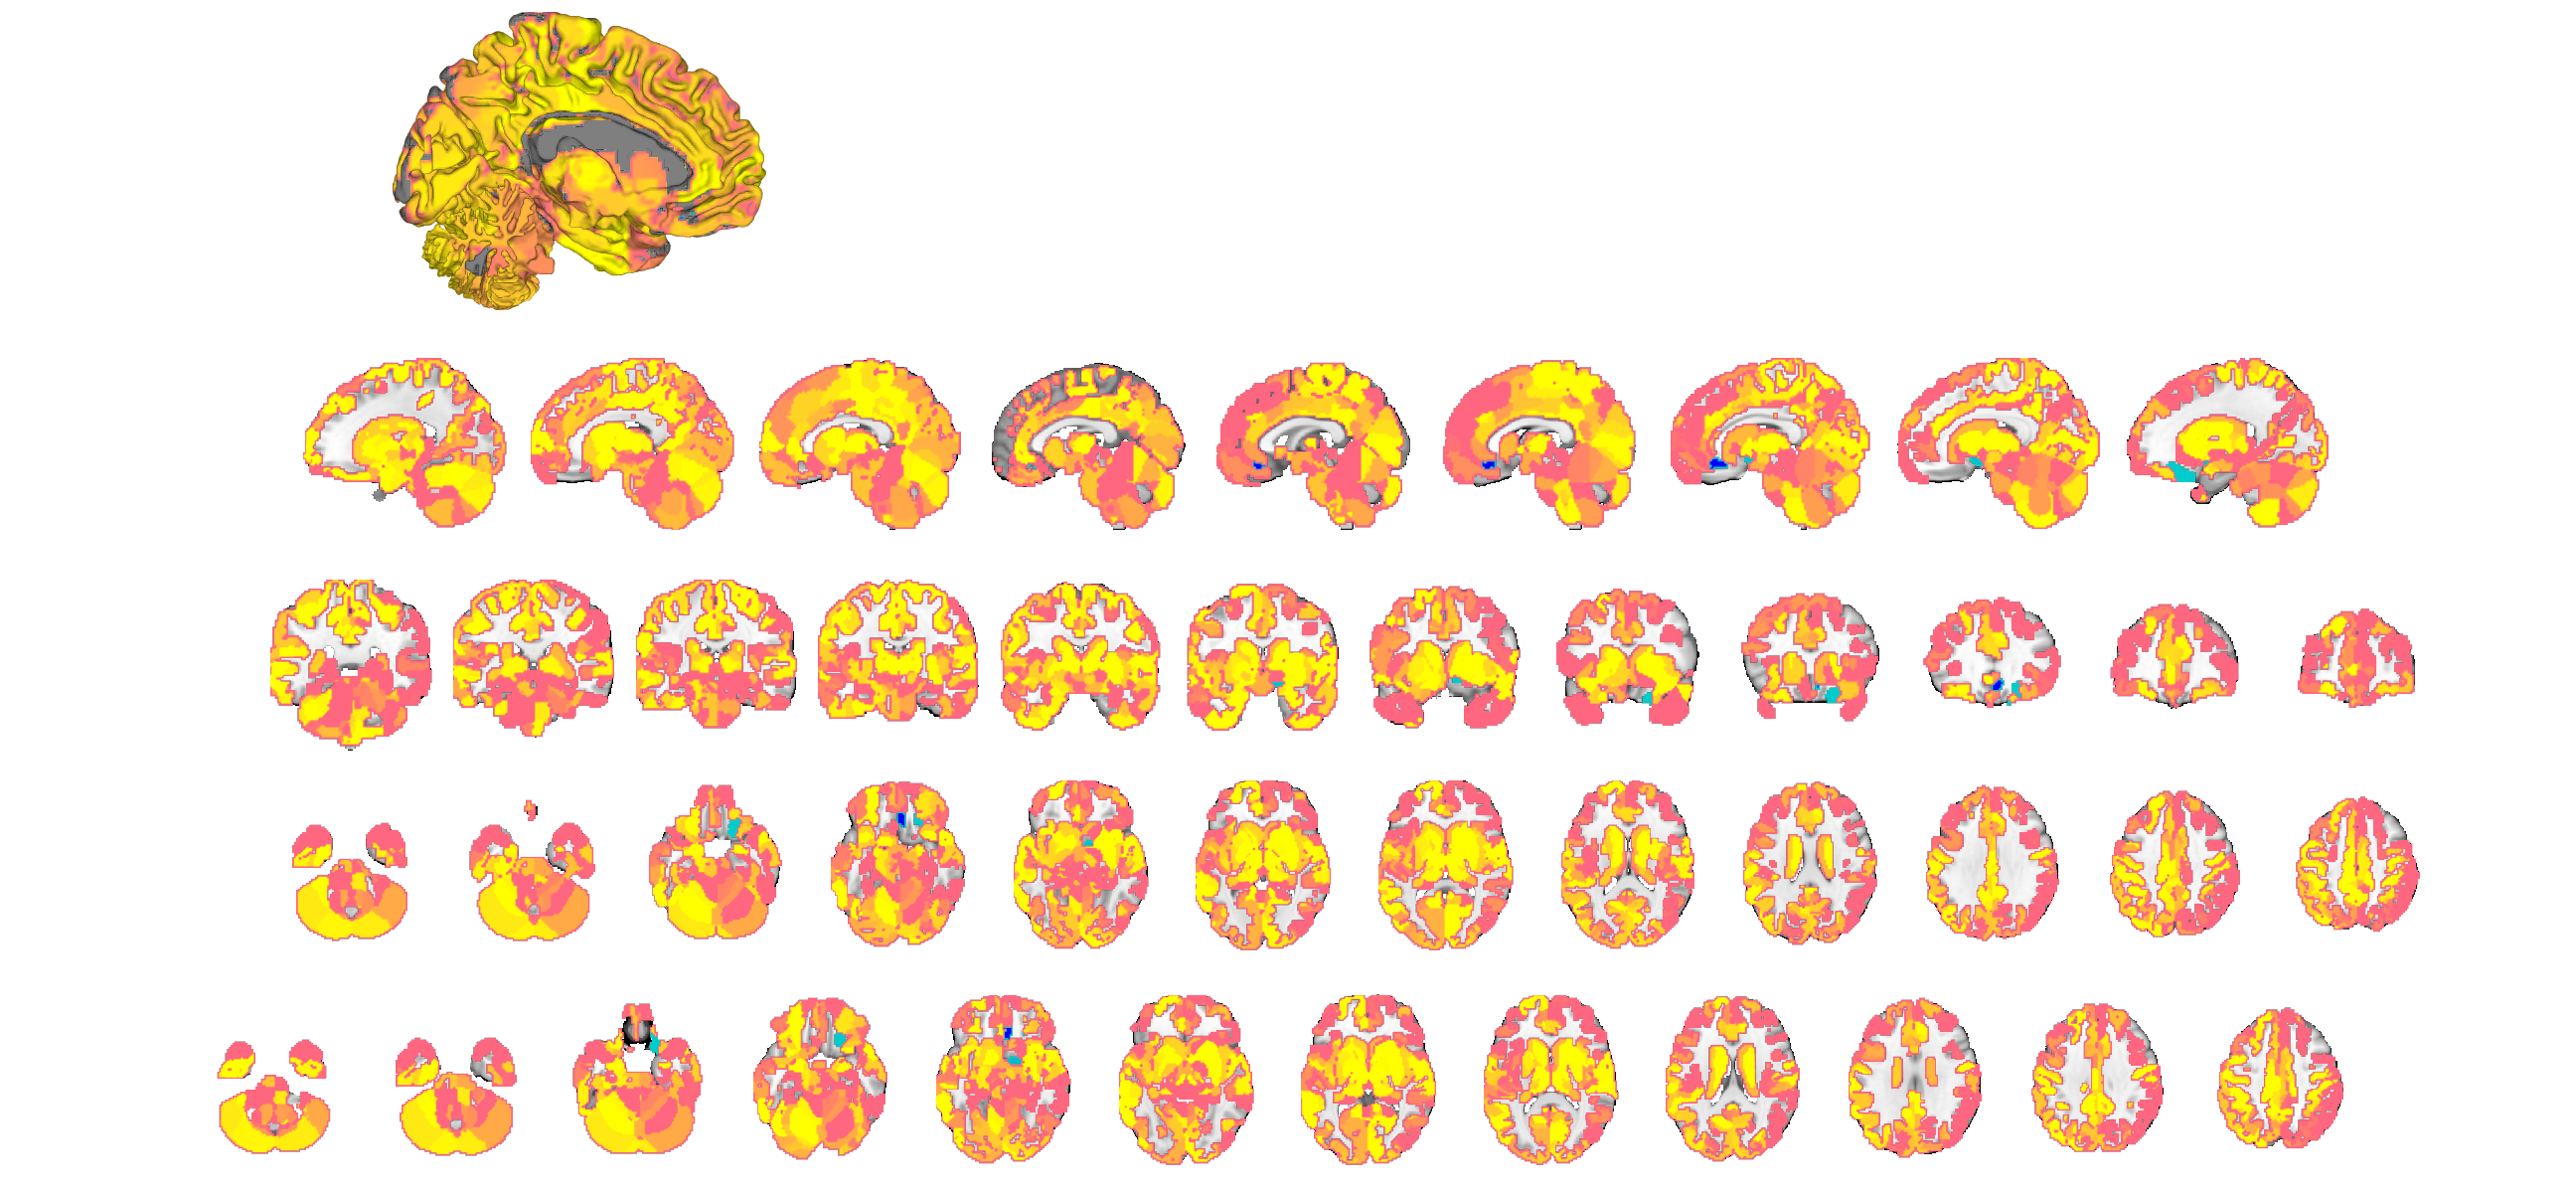

____________________________________________________________________________________________________________________________________________
Positive Effects
           Region             Volume            XYZ            maxZ      modal_label_descriptions      Perc_covered_by_label    Atlas_regions_covered    region_index
    ____________________    __________    ________________    ______    ___________________________    _____________________    _____________________    ____________

    {'Multiple regions'}    1.2897e+06    -4    -26      6    4.9099    {'Cerebellum'             }               2                      447                  1      
    {'Ctx_IFSp_R'      }             8    50     22     26    0.7854   

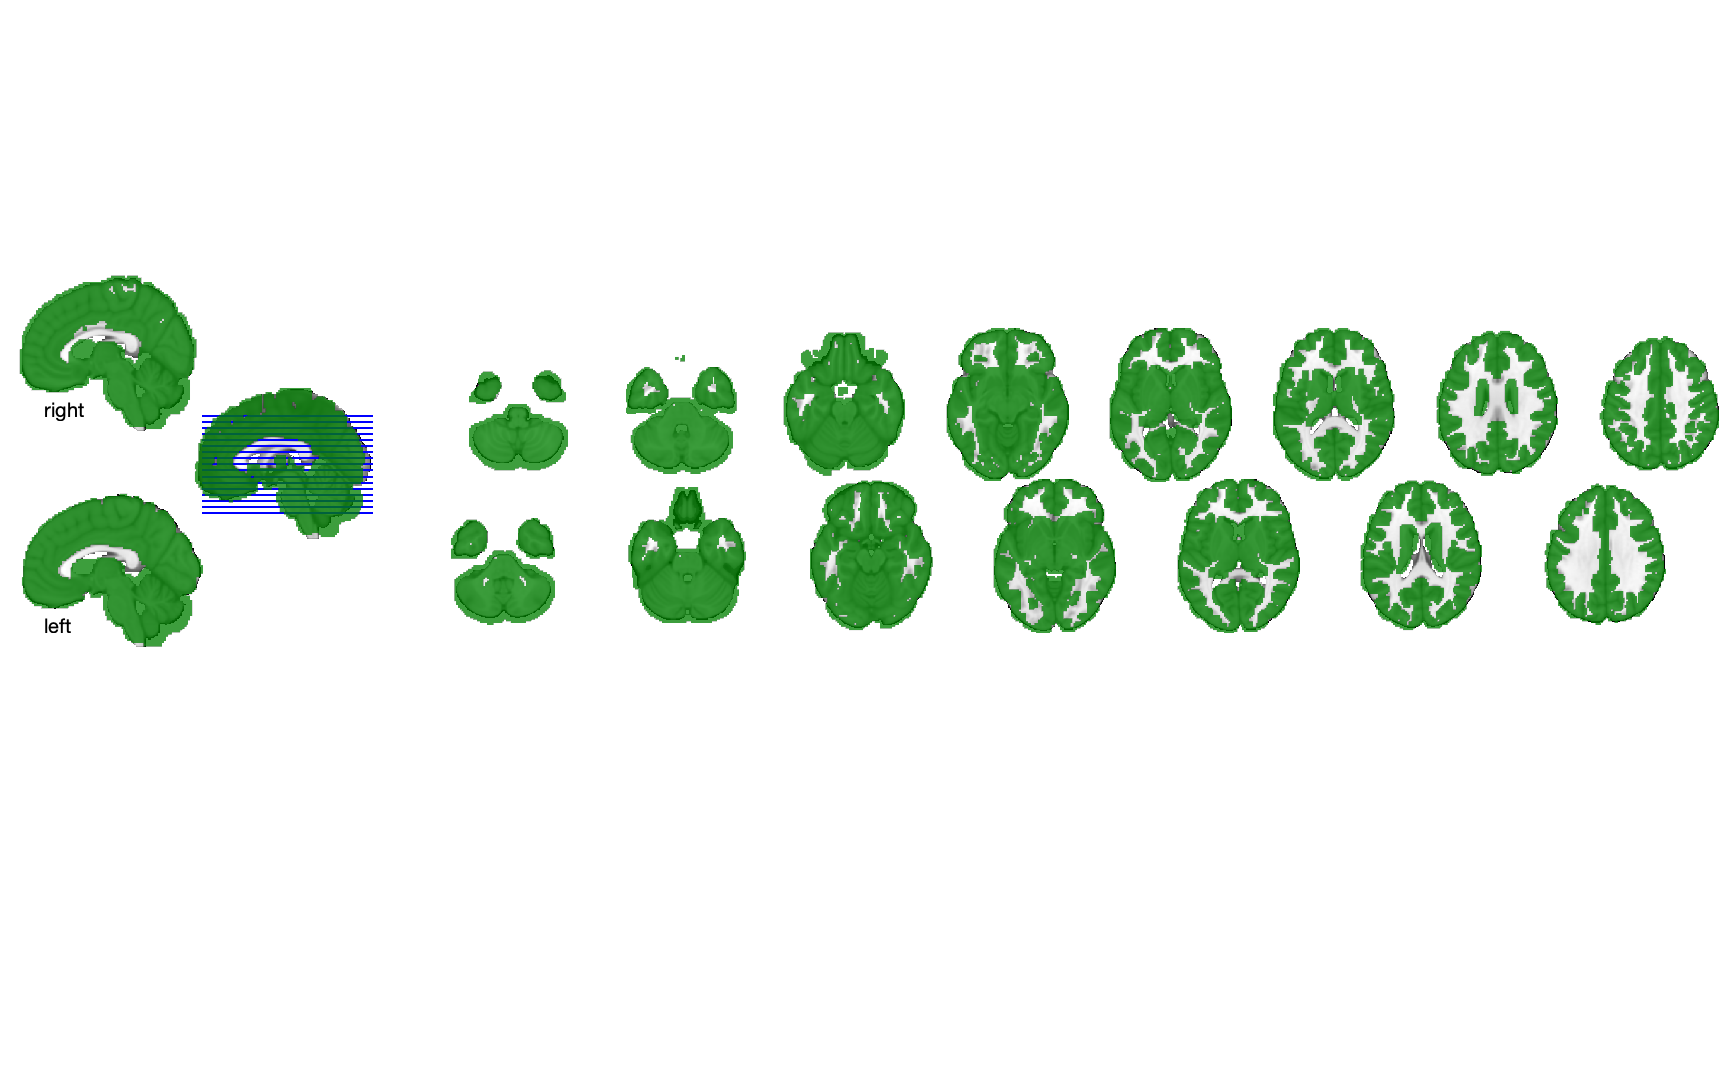

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 21.31%
Expected 3.05 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 8 images		Cases 10 21 23 28 30 31 48 57 
Uncorrected: 9 images		Cases 10 15 21 23 28 30 31 48 57 

Retained 16 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.82%
Expected 3.05 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 41 

Mahalanobis (cov and corr, q<0.05 corrected):
  8 images 
                               Outlier_count    Percentage
          

SPM12: spm_check_registration (v7759)              19:09:06 - 26/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

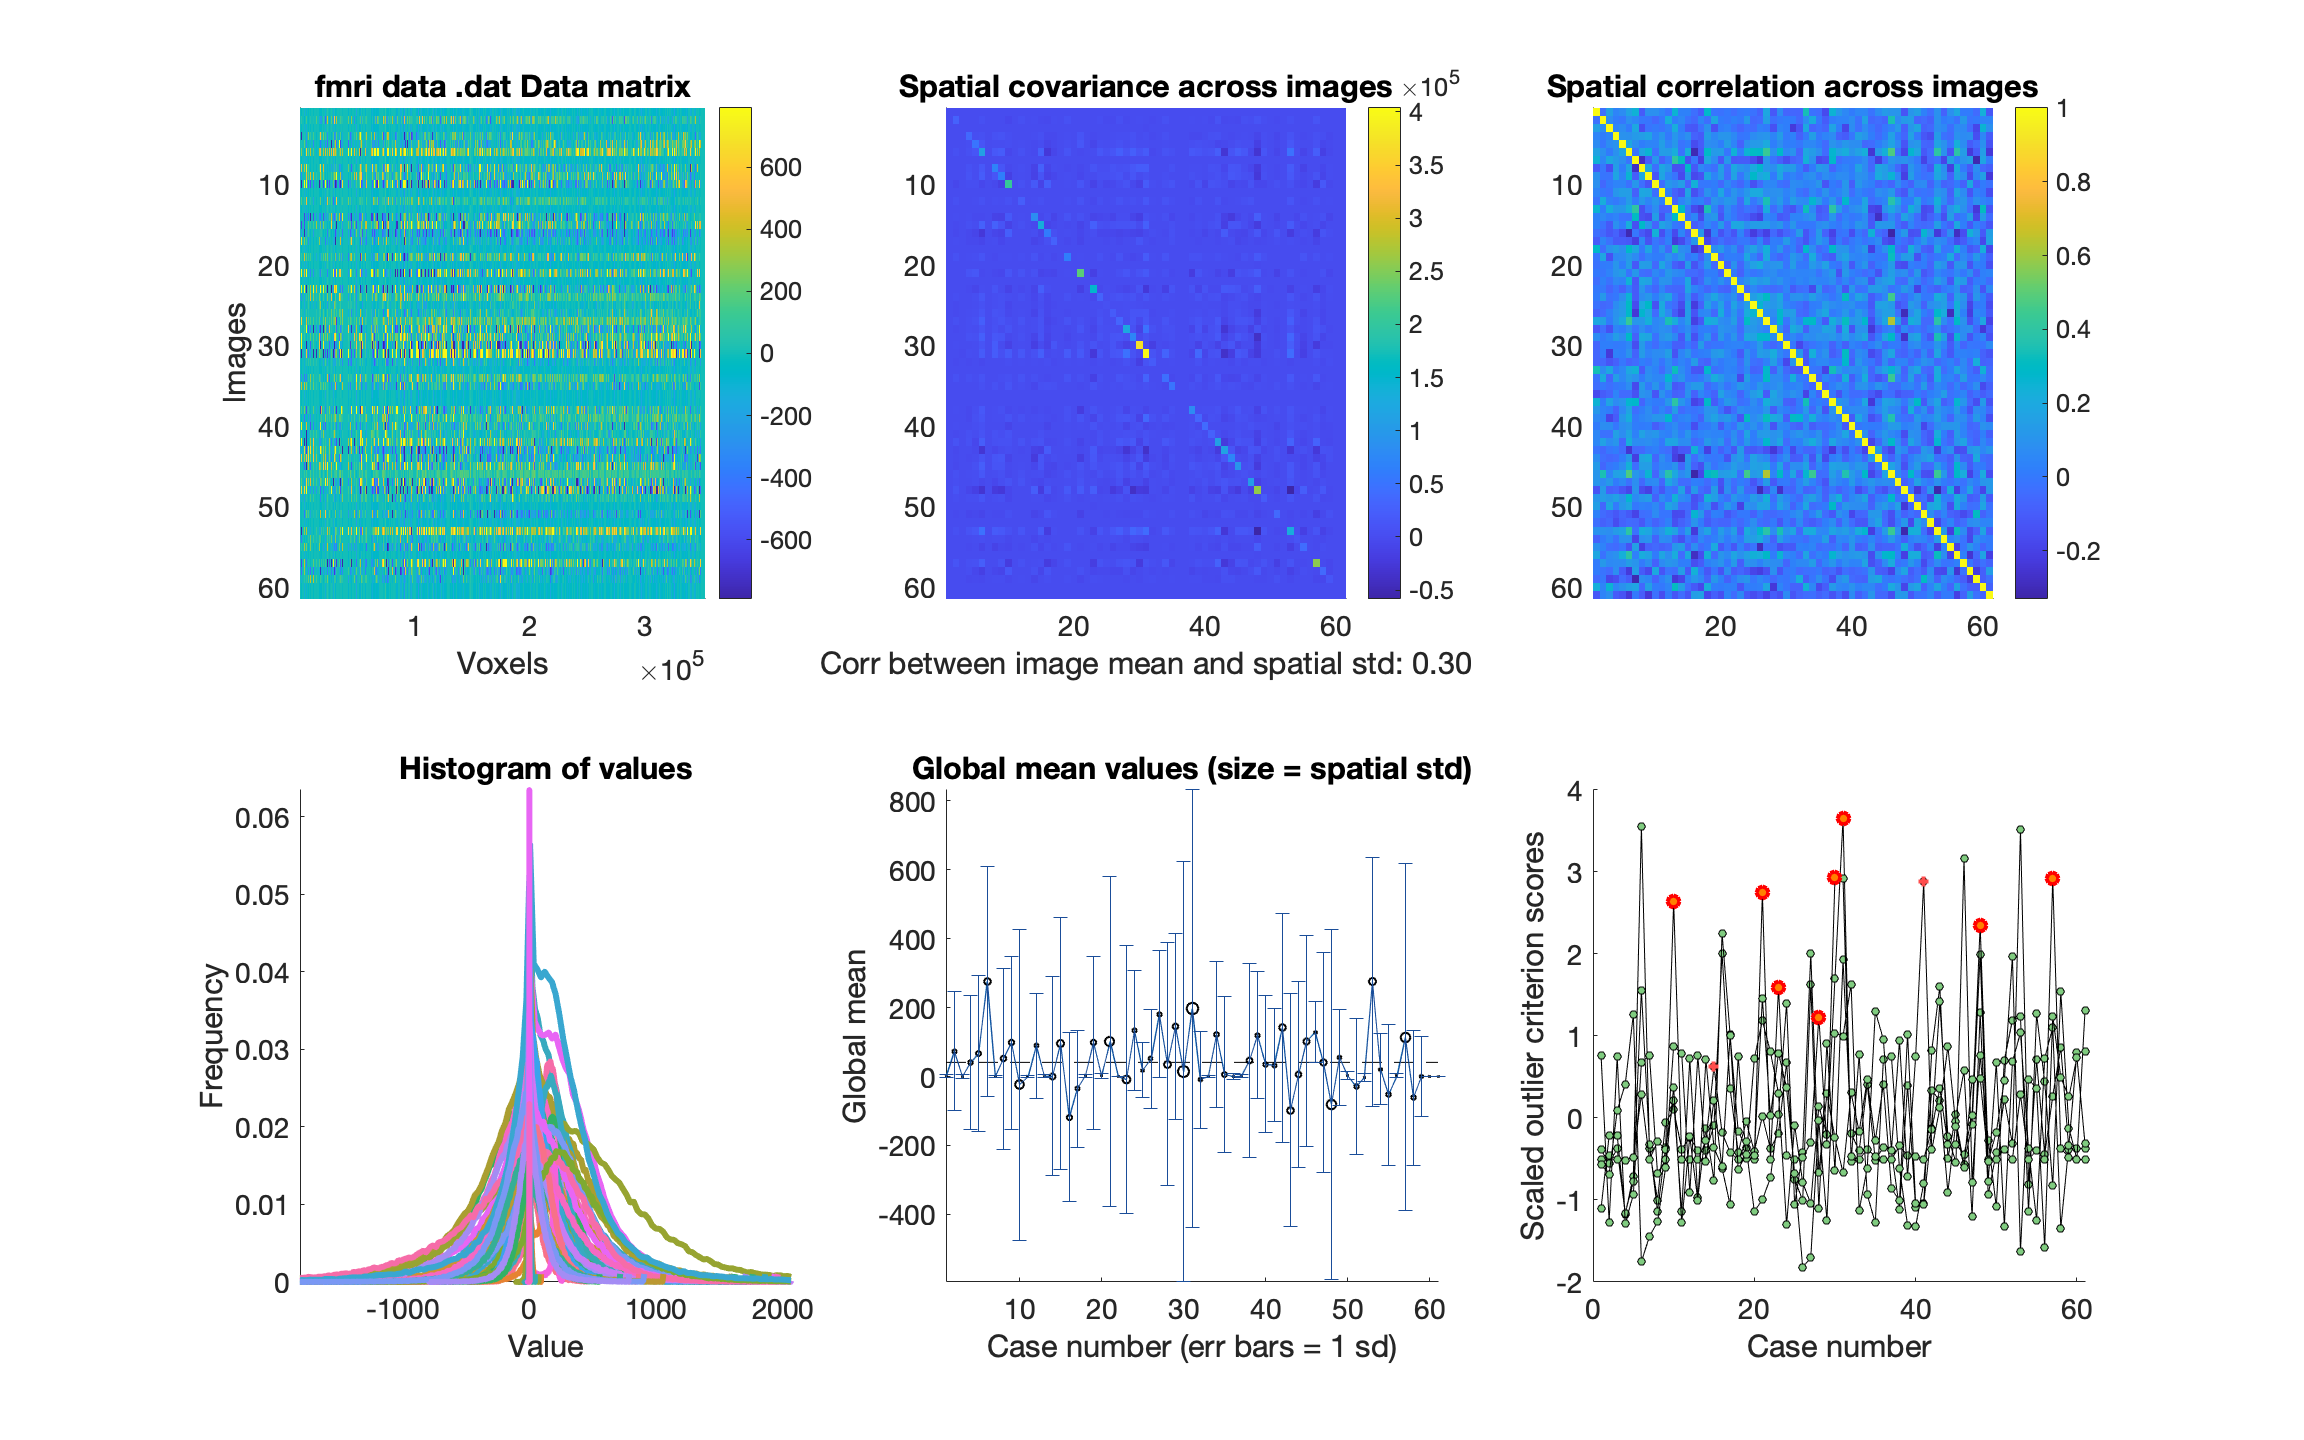

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


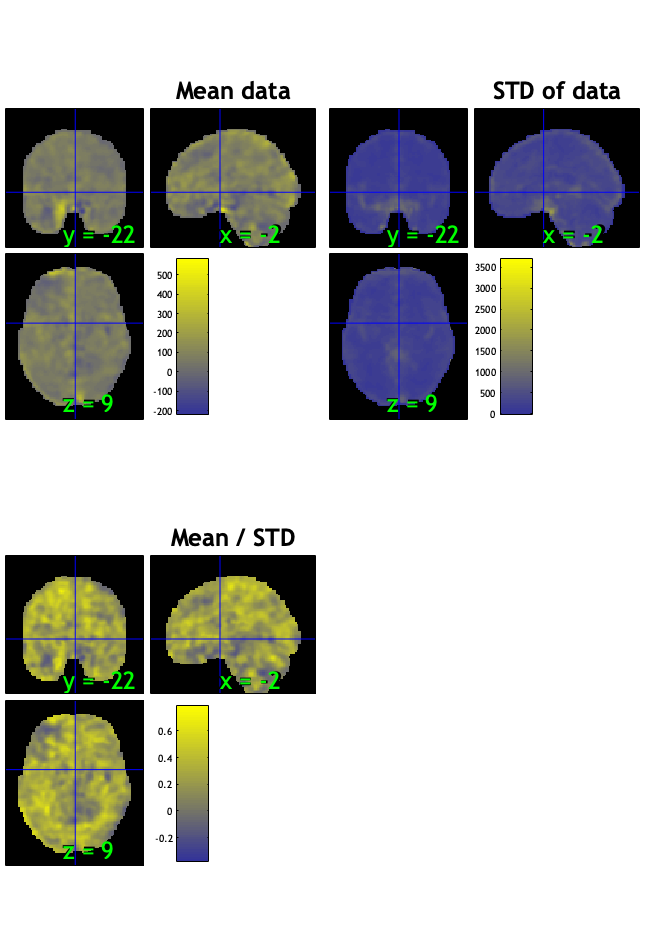

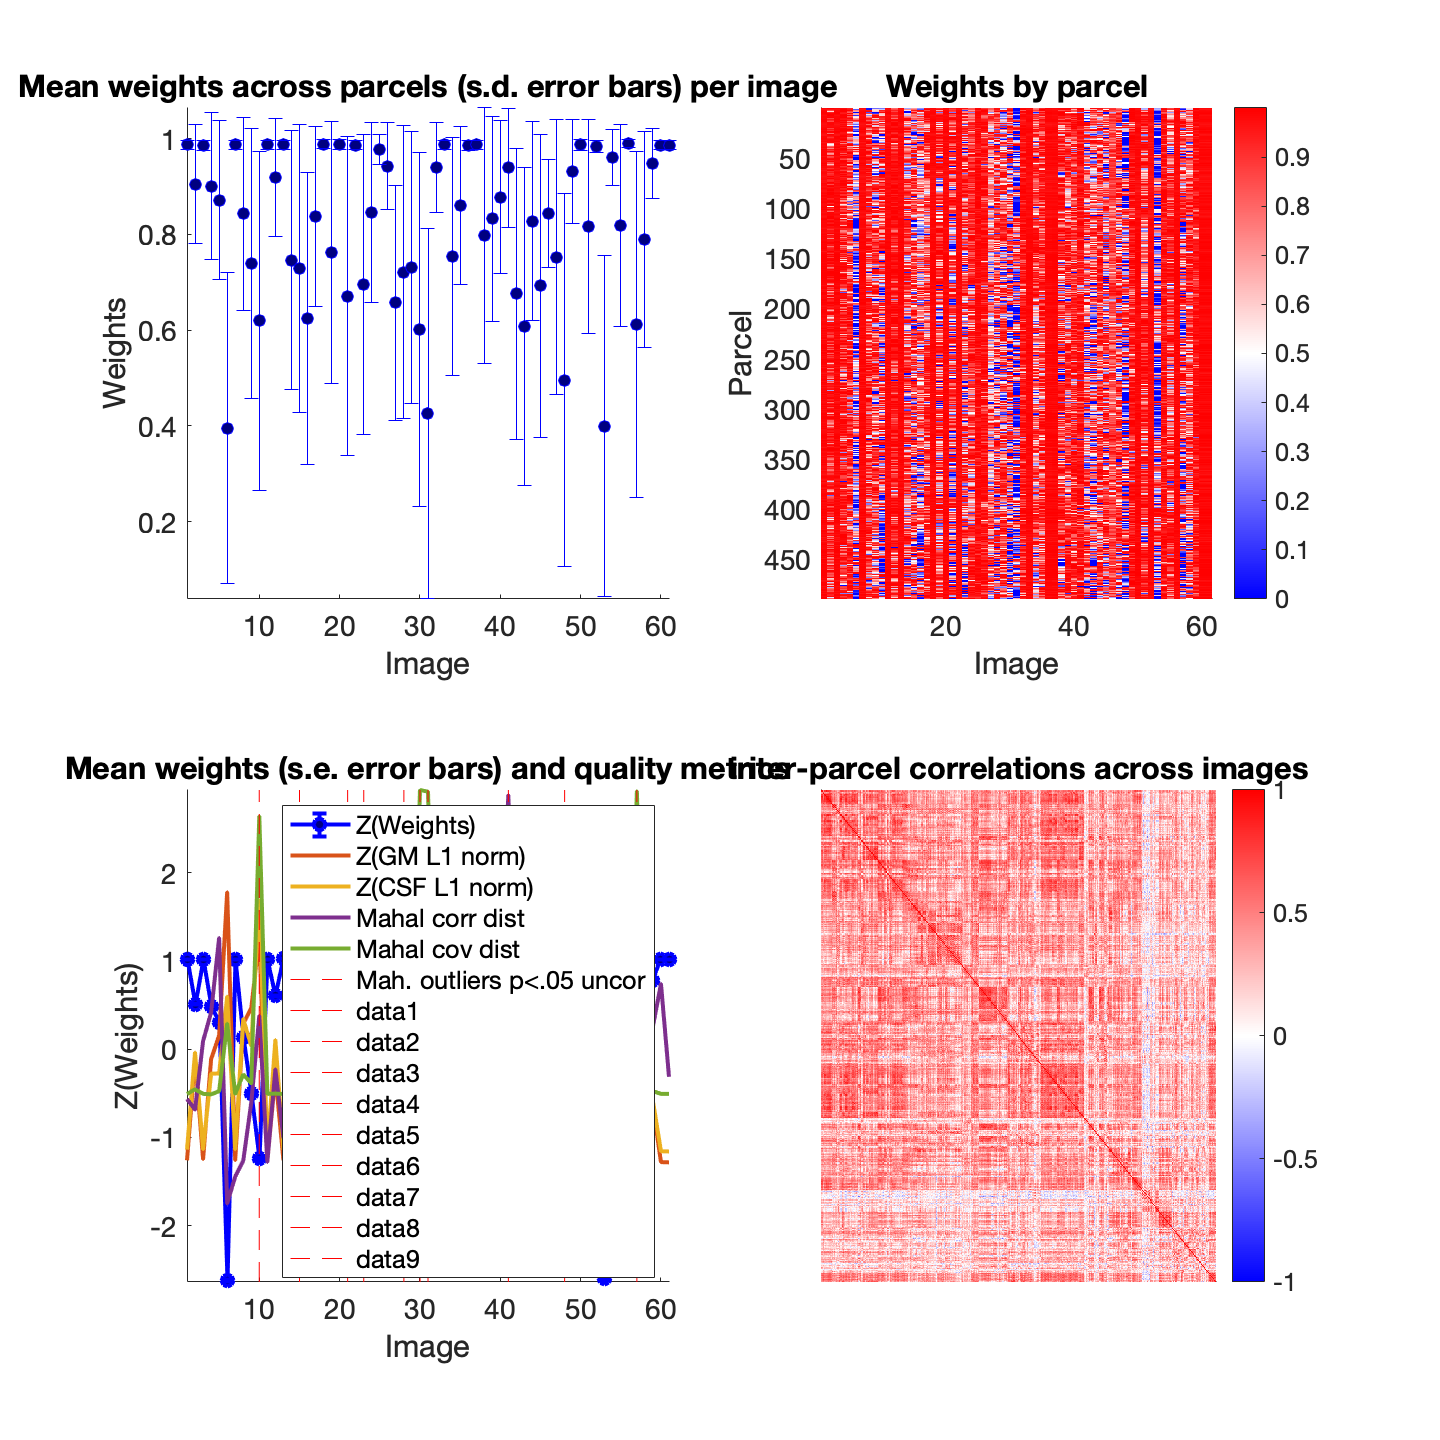

set(gcf,'Visible','on')
figure ('Visible', 'on');
out = robfit_parcelwise(con_data_obj);